clc
clear
close all

bag1 = rosbag('/LAB3/macarena.bag');
bagselect = select(bag1, 'Topic', '/imu');
msgStructs = readMessages(bagselect, 'DataFormat', 'struct');
disp(msgStructs{1}.FullVNYMRString)

$VNYMR,-138.650,+010.404,-020.821,-00.0520,-00.2732,+00.0313,+01.705,+03.292,-09.049,+00.007969,+00.009643,-00.001325*6C



qx = cellfun(@(m) double(m.Imus.Orientation.X),msgStructs);
qy = cellfun(@(m) double(m.Imus.Orientation.Y),msgStructs);
qz = cellfun(@(m) double(m.Imus.Orientation.Z),msgStructs);
qw = cellfun(@(m) double(m.Imus.Orientation.W),msgStructs);

accelx = cellfun(@(m) double(m.Imus.LinearAcceleration.X),msgStructs);
accely = cellfun(@(m) double(m.Imus.LinearAcceleration.Y),msgStructs);
accelz = cellfun(@(m) double(m.Imus.LinearAcceleration.Z),msgStructs);

gyrox = cellfun(@(m) double(m.Imus.AngularVelocity.X),msgStructs);
gyroy = cellfun(@(m) double(m.Imus.AngularVelocity.Y),msgStructs);
gyroz = cellfun(@(m) double(m.Imus.AngularVelocity.Z),msgStructs);

times = cellfun(@(m) double(m.Header.Stamp.Sec),msgStructs);
timens = cellfun(@(m) double(m.Header.Stamp.Nsec),msgStructs);

L = length(msgStructs);

t = zeros(L,1);
eulers = zeros(L,3);
eulers_test = zeros(L,3);

for i = 1:L
    quat1 = [qw(i), qx(i), qy(i), qz(i)];
    eulers(i,:) = (180/pi)*(quat2eul(quat1));
    t(i) = times(i) + timens(i)*10^-9;
end

for i = 1:L 
    line = string(msgStructs{i}.FullVNYMRString);
    data1 = split(line, "*");
    data2 = split(data1(1), ",");

    if length(data2) ~= 13
%         disp(line)
%         disp(data1)
%         disp(data2)
        continue
    else
        eulers_test(i,1) = double(data2(2));
        eulers_test(i,2) = double(data2(3));
        eulers_test(i,3) = double(data2(4));
    end
end

t = t - t(1);
% t = linspace(0, L/40, L);

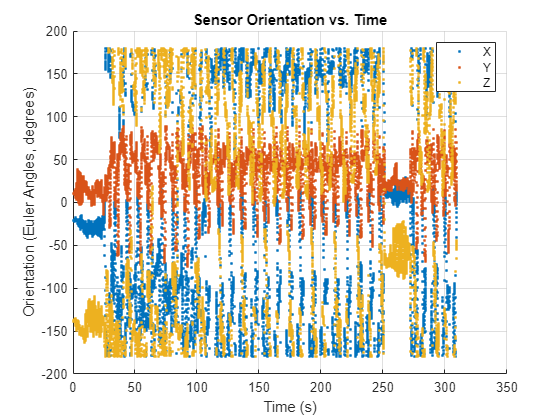

figure
hold on; grid on; scatter(t, [eulers(:,3), eulers(:,2), eulers(:,1)], '.'); title('Sensor Orientation vs. Time');  
xlabel('Time (s)'); ylabel('Orientation (Euler Angles, degrees)'); legend('X', 'Y', 'Z'); 
% set(gcf,'Visible','on'); 
hold off;

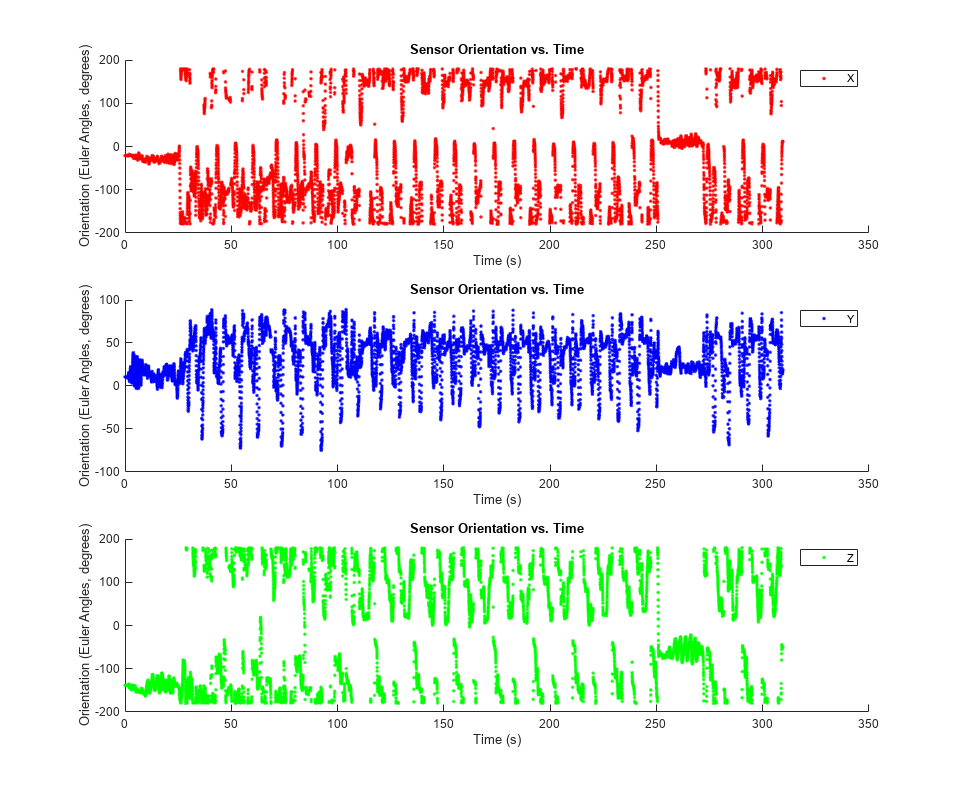


figure
set(gcf, 'position', [0, 0, 1800, 1500])
subplot(3,1,1); grid on; scatter(t, eulers(:,3), '.r'); title('Sensor Orientation vs. Time');  
xlabel('Time (s)'); ylabel('Orientation (Euler Angles, degrees)'); legend('X');

subplot(3,1,2); grid on; scatter(t, eulers(:,2), '.b'); title('Sensor Orientation vs. Time');  
xlabel('Time (s)'); ylabel('Orientation (Euler Angles, degrees)'); legend('Y');

subplot(3,1,3); grid on; scatter(t, eulers(:,1), '.g');  title('Sensor Orientation vs. Time');  
xlabel('Time (s)'); ylabel('Orientation (Euler Angles, degrees)'); legend('Z'); 
% set(gcf,'Visible','on'); 
hold off;

% figure
% set(gcf, 'position', [0, 0, 1800, 1500])
% subplot(3,1,1); grid on; scatter(t, eulers_test(:,3), '.r'); title('RAW DATA');  
% xlabel('Time (s)'); ylabel('Orientation (Euler Angles, degrees)'); legend('X');
% 
% subplot(3,1,2); grid on; scatter(t, eulers_test(:,2), '.b'); title('RAW DATA');  
% xlabel('Time (s)'); ylabel('Orientation (Euler Angles, degrees)'); legend('Y');
% 
% subplot(3,1,3); grid on; scatter(t, eulers_test(:,1), '.g');  title('RAW DATA');  
% xlabel('Time (s)'); ylabel('Orientation (Euler Angles, degrees)'); legend('Z'); set(gcf,'Visible','on'); hold off;

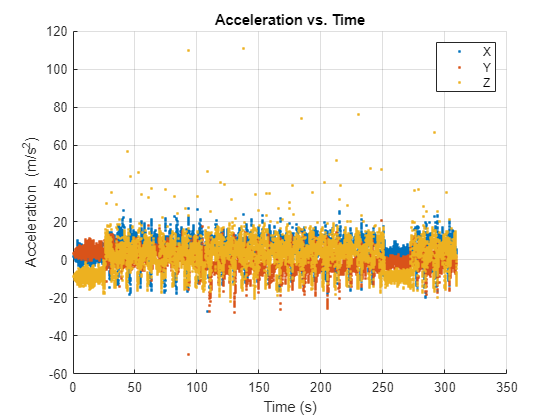

figure
hold on; grid on; scatter(t, [accelx, accely, accelz], '.'); title('Acceleration vs. Time');  
xlabel('Time (s)'); ylabel('Acceleration (m/s^2)'); legend('X', 'Y', 'Z'); hold off;

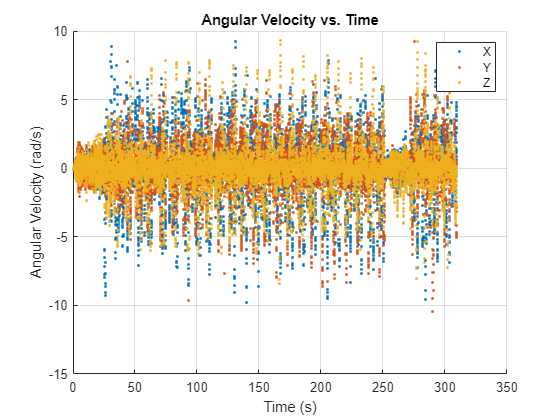

figure
hold on; grid on; scatter(t, [gyrox, gyroy, gyroz], '.'); title('Angular Velocity vs. Time');  
xlabel('Time (s)'); ylabel('Angular Velocity (rad/s)'); legend('X', 'Y', 'Z'); hold off;

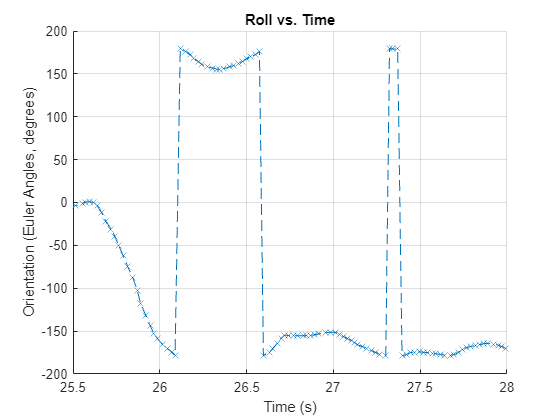

figure
hold on; grid on; plot(t, eulers(:,3), '--x');  title('Roll vs. Time'); xlim([25.5 28]);  
xlabel('Time (s)'); ylabel('Orientation (Euler Angles, degrees)'); 
% set(gcf,'Visible','on'); 
hold off;

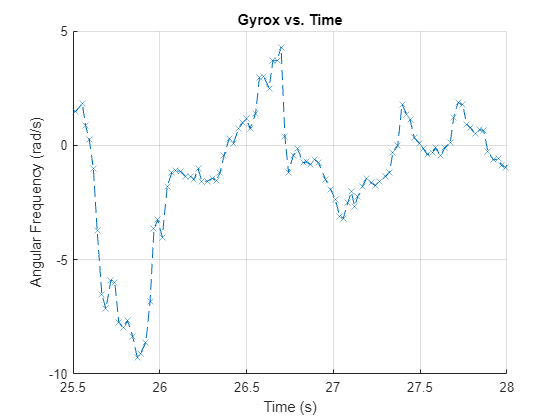


figure
hold on; grid on; plot(t, gyrox, '--x');  title('Gyrox vs. Time'); xlim([25.5 28]);  
xlabel('Time (s)'); ylabel('Angular Frequency (rad/s)'); 
% set(gcf,'Visible','on'); 
hold off;

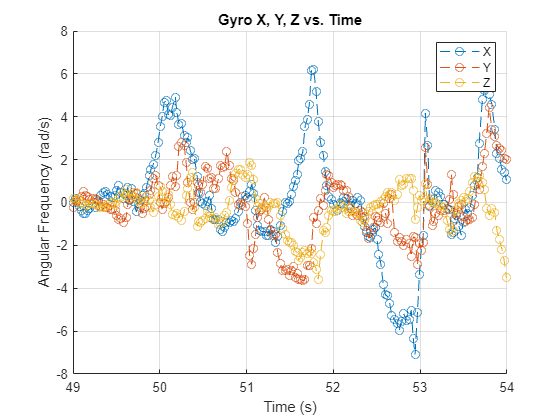

figure
hold on; grid on; plot(t, [gyrox, gyroy, gyroz], '--o'); title('Gyro X, Y, Z vs. Time'); xlim([49 54]);  
xlabel('Time (s)'); ylabel('Angular Frequency (rad/s)'); legend('X', 'Y', 'Z');  
% set(gcf,'Visible','on'); 
hold off;

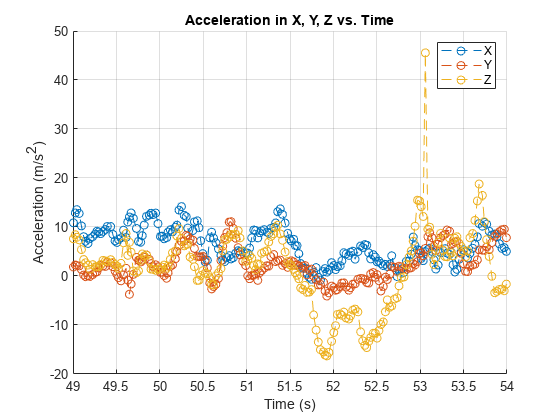


figure
hold on; grid on; plot(t, [accelx, accely, accelz], '--o'); title('Acceleration in X, Y, Z vs. Time'); xlim([49 54]);  
xlabel('Time (s)'); ylabel('Acceleration (m/s^2)'); legend('X', 'Y', 'Z');  
% set(gcf,'Visible','on'); 
hold off;

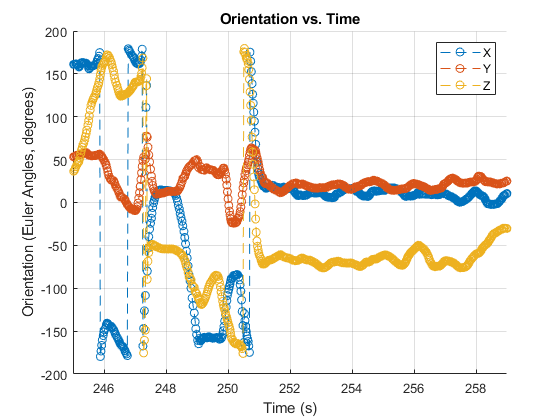

figure
hold on; grid on; plot(t, [eulers(:,3), eulers(:,2), eulers(:,1)], '--o'); title('Orientation vs. Time'); xlim([245 259]);  
xlabel('Time (s)'); ylabel('Orientation (Euler Angles, degrees)'); legend('X', 'Y', 'Z');  
set(gcf,'Visible','on'); 
hold off;

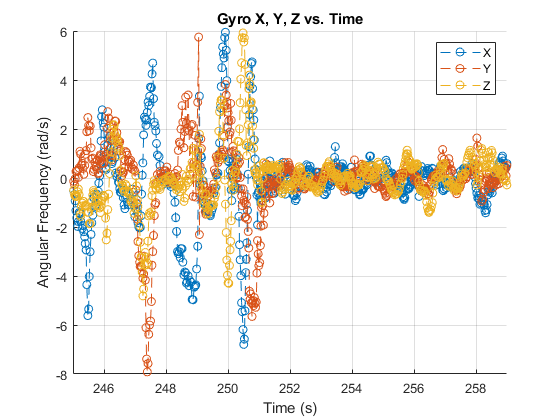


figure
hold on; grid on; plot(t, [gyrox, gyroy, gyroz], '--o'); title('Gyro X, Y, Z vs. Time'); xlim([245 259]);  
xlabel('Time (s)'); ylabel('Angular Frequency (rad/s)'); legend('X', 'Y', 'Z');  
set(gcf,'Visible','on'); 
hold off;

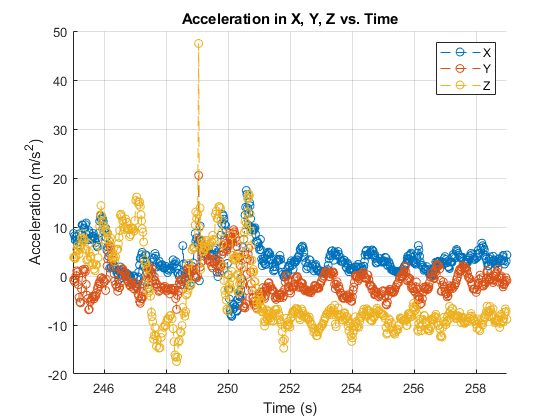


figure
hold on; grid on; plot(t, [accelx, accely, accelz], '--o'); title('Acceleration in X, Y, Z vs. Time'); xlim([245 259]);  
xlabel('Time (s)'); ylabel('Acceleration (m/s^2)'); legend('X', 'Y', 'Z');  
set(gcf,'Visible','on'); 
hold off;